# PROF. AMBROSINO R.___ESAME___20/04/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI 

#### Variabili simboliche 

syms h1 h2 h3 dh1 dh2 dh3 u1 u2 w real

#### Parametri

A1 = 1;
A2 = 1;
A3 = 1;

a12 = 0.6;
a23 = 0.4;
a2 = 0.3;
a3 = 0.25;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [h1;
     h2;
     h3];

% Uscita
y = x;

n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico 


% Equazioni del sistema
eq_1 = -A1*dh1 + u1 - a12*sqrt(h1-h2) == 0;
eq_2 = -A2*dh2 + a12*sqrt(h1-h2) - a23*sqrt(h2-h3) - a2*sqrt(h2) == 0;
eq_3 = -A3*dh3 + u2 + a23*sqrt(h2-h3) - a3*sqrt(h3) == 0;

eqs = [eq_1;
       eq_2;
       eq_3];

sol = solve(eqs, [dh1, dh2, dh3], "ReturnConditions",true);

% dx/dt
f = [sol.dh1;
     sol.dh2;
     sol.dh3];
% y
g = x;

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

eq_dh1_sym = sol.dh1;
eq_dh2_sym = sol.dh2;
eq_dh3_sym = sol.dh3;

x_star_1 = 3.274;
x_star_2 = 2;
x_star_3 = 1.6;

% Punto di Equilibrio
x_star = [x_star_1;
          x_star_2;
          x_star_3];

### 1.1)  Valori di u1* e u2* che rendono x* un punto di equilibrio 


eq_dh1 = subs(eq_dh1_sym, {h1, h2, h3}, {x_star_1, x_star_2, x_star_3}) == 0;
eq_dh3 = subs(eq_dh3_sym, {h1, h2, h3}, {x_star_1, x_star_2, x_star_3}) == 0;

u_star_sol = solve([eq_dh1, eq_dh3], [u1, u2], 'ReturnConditions',true);

u1_star = double(u_star_sol.u1);
u2_star = double(u_star_sol.u2);

disp(table(x_star_1, x_star_2, x_star_3, u1_star, u2_star));

    x_star_1    x_star_2    x_star_3    u1_star    u2_star 
    ________    ________    ________    _______    ________

     3.274         2          1.6       0.67723    0.063246



### 1.2)  Modello Linearizzato nell'intorno di (x*, u*)

u_star = [u1_star;
          u2_star];

A_sym = jacobian(f, x);
B_sym = jacobian(f, u);
C_sym = jacobian(g, x);
D_sym = jacobian(g, u);

### 1.3)  Matrici del Sistema

A = double(subs(A_sym, [x; u], [x_star; u_star]));
B = double(subs(B_sym, [x; u], [x_star; u_star]));
C = double(subs(C_sym, [x; u], [x_star; u_star]));
D = double(subs(D_sym, [x; u], [x_star; u_star]));

sys = ss(A, B, C, D)


sys =
 
  A = 
            x1       x2       x3
   x1  -0.2658   0.2658        0
   x2   0.2658  -0.6881   0.3162
   x3        0   0.3162   -0.415
 
  B = 
       u1  u2
   x1   1   0
   x2   0   0
   x3   0   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


### 1.4) Verifica Stabilità x*, raggiungibilità e osservabilità sistema

#### Stabilità

% Approccio agli autovalori

autovalori_A = eig(A);

if (all(autovalori_A < 0))
    disp('Il punto di equiibrio è asintoticamente stabile'); autovalori_A
elseif (any(autovalori_A == 0))
    disp('Il punto di equilibrio è stabile'); autovalori_A
else
    disp('Il punto di equilibrio è instabile'); autovalori_A
end

Il punto di equiibrio è asintoticamente stabile


autovalori_A =    -0.9690
   -0.3390
   -0.0609


#### Raggiungibilità

if (rank(ctrb(A,B)) == n)
    disp('Il sistema è completamente raggiungibile');
else
    disp('Il sistema NON è completamente raggiungibile');
end

Il sistema è completamente raggiungibile


#### Osservabilità

if (rank(obsv(A,C)) == n)
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## 2)  CONTROLLO STABILIZZANTE MEDIANTE APPROCCIO ALLA LYAPUNOV

#### Specifiche

% Stato iniziale
h0 = [0.3;
      0.2;
      0.1];

C_sel = C(1:2,:);

% Riferimento
h1_ref_lmi = 0.5;
h2_ref_lmi = 0.4;

h_ref = [h1_ref_lmi;
         h2_ref_lmi];

#### Risoluzione con cvx

cvx_clear;
cvx_begin sdp quiet
    cvx_precision high
    variable Q(n,n) symmetric
    variable L(m,n)
    minimize(0);
    subject to
        Q >= (1e-6)*eye(n);
        A*Q + Q*A' + B*L + L'*B' <= (1e-6)*eye(n);
cvx_end;

K_LMI = -L/Q

K_LMI =     0.2260    0.5389   -0.0185
   -0.0011    0.6404    0.0733


#### Compensazione del Guadagno

gain = dcgain(ss((A-B*K_LMI), B, C_sel, D(1:2, 1:2)));
N = pinv(gain)

N =     0.5073    0.2328
   -0.4115    1.3868


#### Verifica Simulazione

Schema Simulink: [**Verifica_LMI**](matlab:open_system('Verifica_LMI_20042026.slx'))

## 3)  CONTROLLO LQR CON AZIONE INTEGRALE

#### Specifiche

h2_ref_lqr = 2.8;

Ts = 1;
alpha = 4/Ts;

#### Sistema Aumentato 

A_aug = [A      , zeros(n,1);
         -C(2,:), 0];

n_aug = size(A_aug,1);

B_aug = [B;
         zeros(1,m)];

C_aug = [C zeros(n,1)];

% D_aug = [D;
%          zeros(1,m)];

sys_aug = ss(A_aug, B_aug, C_aug, D)


sys_aug =
 
  A = 
            x1       x2       x3       x4
   x1  -0.2658   0.2658        0        0
   x2   0.2658  -0.6881   0.3162        0
   x3        0   0.3162   -0.415        0
   x4        0       -1        0        0
 
  B = 
       u1  u2
   x1   1   0
   x2   0   0
   x3   0   1
   x4   0   0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


#### Sintesi

% Shift di A_aug per rispettare la specifica sul tempo di assestamento 
A_hat = A_aug -alpha*eye(n_aug);
eig(A_hat)

ans =    -4.0000
   -4.9690
   -4.0609
   -4.3390


Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 20)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0    20


R = eye(m)

R =      1     0
     0     1


K_LQR = lqr(sys_aug, Q, R)

K_LQR =     1.2843    3.1771    0.5972   -2.9032
    0.5972    3.6912    1.3598   -3.4017


K_LQR_x = K_LQR(:, 1:n)

K_LQR_x =     1.2843    3.1771    0.5972
    0.5972    3.6912    1.3598


K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i =    -2.9032
   -3.4017


#### Verifica Simulazione

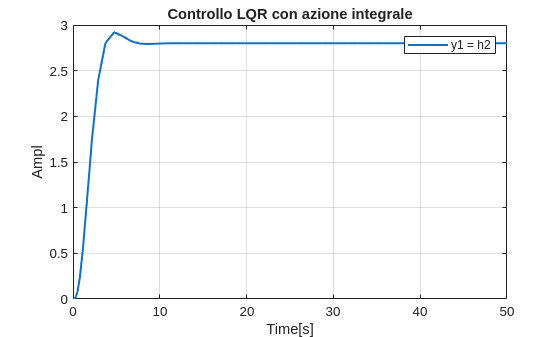

% Plot MATLAB
out = sim('Verifica_LQR_20042026.slx');
y1_lqr = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = h2');
title('Controllo LQR con azione integrale');

**Lo schema Simulink è consultabile dal seguente link**

Schema simulink:  [Verifica_LQR](matlab:open_system('Verifica_LQR_20042026.slx'))

## **4)  CONTROLLO H-INF**

#### Sistema con Disturbo

% Equazione con disturbo
eq_2 = -A2*dh2 + a12*sqrt(h1-h2) - a23*sqrt(h2-h3) - a2*sqrt(h2) + w == 0;

eqs_w = [eq_1;
         eq_2;
         eq_3];

sol_w = solve(eqs_w, [dh1, dh2, dh3], "ReturnConditions",true);

% dx/dt
f_w = [sol_w.dh1;
       sol_w.dh2;
       sol_w.dh3];

u_w = [w;
       u];

ro = 0.1;

% y
z = [x;
     ro*u];

g_w = [z;
       y];

A_w_sym = jacobian(f_w, x);
B_u_sym = jacobian(f_w, u);
B_w_sym = jacobian(f_w, w);
C_w_sym = jacobian(g_w, x);
D_w_sym = jacobian(g_w, u_w);

B_tot_sym = jacobian(f_w, u_w);

A_w = double(subs(A_w_sym, [x; u], [x_star; u_star]));
B_u = double(subs(B_u_sym, [x; u], [x_star; u_star]));
B_w = double(subs(B_w_sym, [x; u], [x_star; u_star]));
C_w = double(subs(C_w_sym, [x; u], [x_star; u_star]));
D_w = double(subs(D_w_sym, [x; u], [x_star; u_star]));

B_tot = double(subs(B_tot_sym, [x; u], [x_star; u_star]));

sys_w = ss(A_w, [B_w B_u], C_w, D_w)


sys_w =
 
  A = 
            x1       x2       x3
   x1  -0.2658   0.2658        0
   x2   0.2658  -0.6881   0.3162
   x3        0   0.3162   -0.415
 
  B = 
       u1  u2  u3
   x1   0   1   0
   x2   1   0   0
   x3   0   0   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
   y4   0   0   0
   y5   0   0   0
   y6   1   0   0
   y7   0   1   0
   y8   0   0   1
 
  D = 
           u1      u2      u3
   y1       0       0       0
   y2       0       0       0
   y3       0       0       0
   y4       0  0.0001       0
   y5       0       0  0.0001
   y6       0       0       0
   y7       0       0       0
   y8       0       0       0
 
Continuous-time state-space model.


B_w

B_w =      0
     1
     0


#### Sintesi H-inf

[K_HINF, ~, gamma] = hinfsyn(sys_w, p, m);
K_HINF


K_HINF =
 
  A = 
            x1       x2       x3
   x1   -1e+04    -3319   -1.793
   x2   -1.331  0.09125   -6.837
   x3  -0.5271    -3949   -1e+04
 
  B = 
             u1        u2        u3
   x1    0.3915  0.001559     1.688
   x2     1.597  0.009202     7.154
   x3    0.4221  0.001746      1.84
 
  C = 
           x1      x2      x3
   y1  -1e+04   -3320  -0.105
   y2  -0.105   -3950  -1e+04
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.


% Controllo 
if gamma>1
    disp('MIXSYN  FAILED:');
    double(gamma)
else
    fprintf("\n---- MIXSYN RESULT ----\n");
    double(gamma)
end

MIXSYN  FAILED:


ans = 1.2547